% Read the audio file
[y, f] = audioread('MUHA.wav');

% Get the time vector
dt = 1/f;
T = length(y)*dt;
t = 0:dt:T-dt;

% Get the frequency vector
dv = 1/T;
v = -f/2:dv:f/2-dv;

% Define the low-pass filter parameters


Нам здесь нужно будет применить два фильтра - сначала режем низкие частоты, потом - высокие

Пришлось применить несколько другие функции матлаба, потому что умножать такие большие массивы поэлементно в лоб матлаб *не хочет давать* - оперативки не хватит

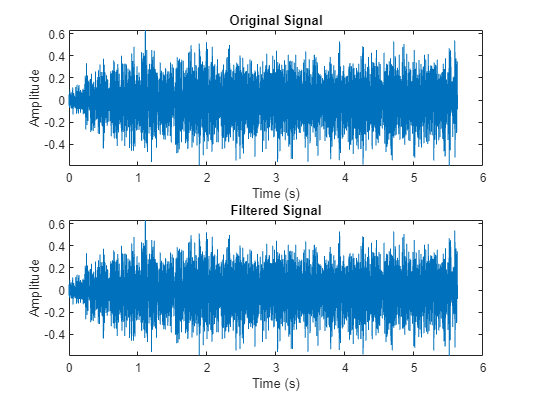

fc = 350; % Cutoff frequency in Hz
% 350 - 4000 Hz
% Create the low-pass filter function
g_t_low = ones(size(y));
g_t_low((v >= -fc) & (v <= fc)) = 0;

fc_low = 350; % Cutoff frequency in Hz
fc_high = 4000; % Cutoff frequency in Hz
g_t_high = ones(size(y));
g_t_high((v < -fc) & (v > fc)) = 0;


g_t( ( (v > -fc_high) & (v < -fc_low) ) & ( (v > fc_low) & (v < fc_high) ) ) = 0;

% Apply the filter to the signal
Y = fft(y);
% Y_filtered = (Y .* g_t_low).*g_t_high;
Y_filtered = Y .*g_t;
y_filtered = real(ifft(Y_filtered));

% Plot the original and filtered signals
subplot(2, 1, 1);
plot(t, y);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, y_filtered);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');


% sound(y,f); % play the sound
sound(y_filtered,f); % play the sound
